## **PROCESSING EMG DATA**

This script tries to analyze the data acquired by EMG electrodes placed on the vastus lateralis and biceps femoralis in order to obtain their RMS values in a 100-ms window for making comparisons between healthy patients and osteoporotic ones.

clear all
clc
close all

### Loading of EMG signals for vastus lateralis

healthy = csvread('EMG_vastus_lateralis_Ida_18_05_1.csv'); %healty patient signal (IDA)
osteoporotic = csvread('EMG_vastus_lateralis_Zia_20_05_1.csv'); %osteoporotic patient signal (ZIA)

Signal parameters

fc_h=load('Sampling_frequency_vastus_Zia_20_05_1.txt'); %measured during data acquisition
fc_o=load('Sampling_frequency_Ida_18_05_1.txt'); %measured during data acquisition

fc=max(max(fc_h),max(fc_o));;

f_low = 20; 
f_high = 450;
window_size = 100; %ms

Calculation of acquisition time and time axes

min_sig=min(length(healthy),length(osteoporotic));

healthy=healthy(1:min_sig);
osteoporotic=osteoporotic(1:min_sig);

T=size(healthy,1)/fc;
t=0:1/fc:(T-1/fc);

Take a look at the newly acquired signals

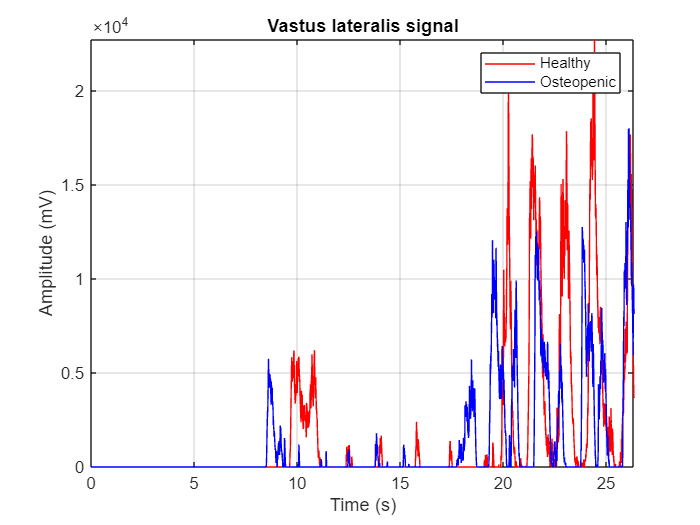

figure()
plot(t,healthy,'r',t,osteoporotic,'b'), title('Vastus lateralis signal');
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;
legend('Healthy','Osteopenic'),axis tight;

### **Filtering the signal with a second-order Butterworth filter**

Signal has already been filtered between 20 and 450 Hz; there's no need to remove the mean value because it has already been eliminated.

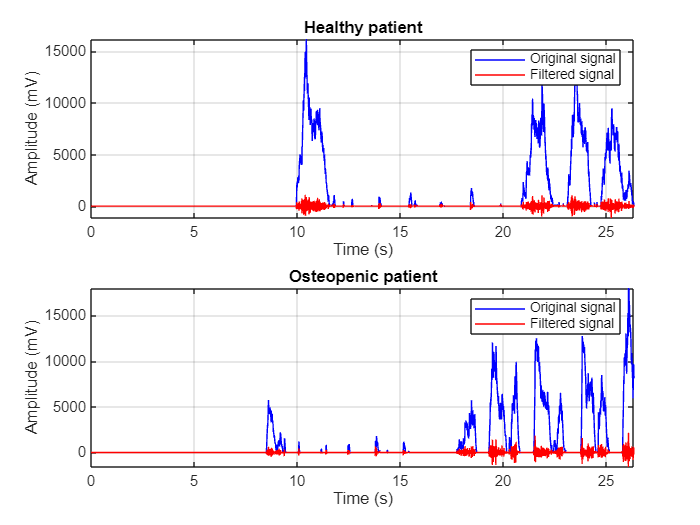

[b, a] = butter(2, [f_low, f_high] / (fc/2), 'bandpass');
healthy_filtered = filtfilt(b, a, healthy);
osteoporotic_filtered = filtfilt(b, a, osteoporotic);

figure
% Subplot 1: comparison between original healthy signal and filtered healthy signal
subplot(2,1,1);
plot(t, healthy, 'b', t, healthy_filtered, 'r');
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;
title('Healthy patient'),legend('Original signal', 'Filtered signal'),axis tight;

% Subplot 2: comparison between original osteoporotic signal and filtered osteoporotic signal
subplot(2,1,2);
plot(t, osteoporotic, 'b', t, osteoporotic_filtered, 'r');
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;
title('Osteopenic patient'),legend('Original signal', 'Filtered signal'),axis tight;

### **Normalization to MVIC (Maximum Voluntary Isometric Contraction)**

According to the protocol, an isolated acquisition is made in which the patient is asked to contract for a maximum of 5' with the leg in extension and take the average value from these acquisitions as the MVIC value. 

%max_sig=max(max(healthy_filtered),max(osteoporotic_filtered));

healthy_max = csvread('EMG_vastus_lateralis_Ida_18_05_max_1.csv'); %vastus lateralis signal during MIVC
osteoporotic_max = csvread('EMG_vastus_lateralis_Zia_20_05_max_1.csv'); %biceps femoris signal during MIVC

mean_sig=mean(healthy_max);
healthy_normalized = healthy_filtered / mean_sig;

mean_sig=mean(osteoporotic_max);
osteoporotic_normalized = osteoporotic_filtered / mean_sig;

Plot of the normalized signals

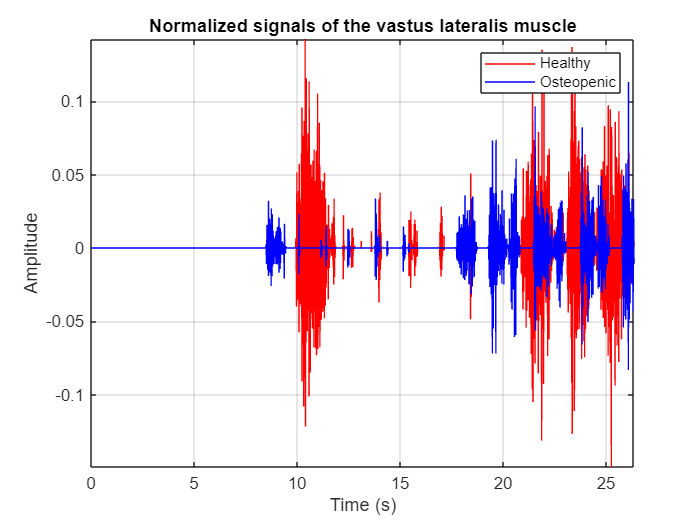

figure()
plot(t,healthy_normalized,'r',t,osteoporotic_normalized,'b');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
title('Normalized signals of the vastus lateralis muscle'), legend('Healthy','Osteopenic'),axis tight;

### Compute RMS values in 100 ms windows

Use of the RMS function

[rms_values_h, num_windows1] = calculate_windowed_rms(healthy_filtered, window_size, fc);
[rms_values_o, num_windows2] = calculate_windowed_rms(osteoporotic_filtered, window_size, fc);

Plot of results: those are the plots of our interest

Comparison of RMS value between healthy subject (Camilla) and osteoporotic subject (aunt) as two signals in the same plot in which I highlight the point at which the peak is reached and the time taken to reach the peak.

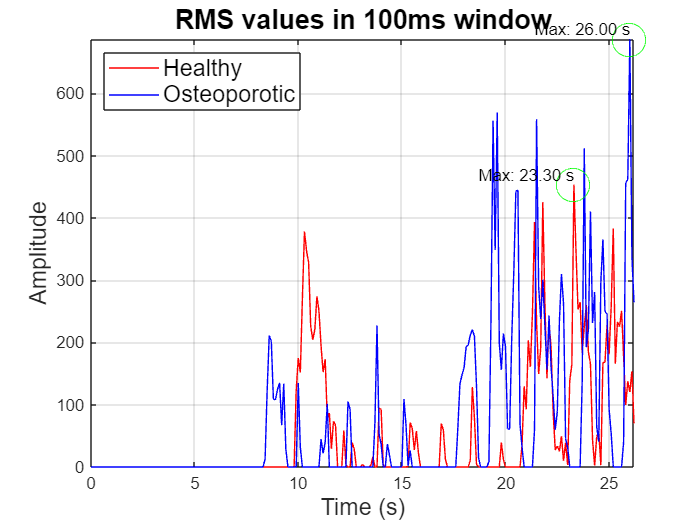

time_axis = (0:num_windows1-1) * window_size / 1000; % Asse del tempo (secondi)

[max_h, idx_h] = max(rms_values_h);
[max_o, idx_o] = max(rms_values_o);

time_max_h = time_axis(idx_h);
time_max_o = time_axis(idx_o);

figure;
plot(time_axis, rms_values_h, 'r', time_axis, rms_values_o, 'b'),axis tight;
hold on;

plot(time_max_h, max_h, 'go', 'MarkerSize', 20);
plot(time_max_o, max_o, 'go', 'MarkerSize', 20);

text(time_max_h, max_h, sprintf('Max: %.2f s', time_max_h), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(time_max_o, max_o, sprintf('Max: %.2f s', time_max_o), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

legend('Healthy', 'Osteoporotic','FontSize', 14,'Location','northwest');
xlabel('Time (s)', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('RMS values in 100ms window', 'FontSize', 16);
grid on;
axis tight;
hold off;